# FNN CNN LSTM - Get Data Plot

## Set index of each items of data

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;
charVIT_Index = i; 


load cap_gen_05_org
load cap_gen_06_org
load cap_gen_07_org
load cap_gen_05
load cap_gen_06
load cap_gen_07

load cap_05             
load cap_06             
load cap_07             
load cap_0506           
load cap_0605           
load cap_05plus06       
load cap_05plus07       
load cap_06plus07       
load cap_05plus06plus07 

load pattern_temp_05_const        
load pattern_temp_06_const        
load pattern_temp_07_const        
load pattern_CC_amps_05_const     
load pattern_CC_amps_06_const     
load pattern_CC_amps_07_const     
load pattern_dVolt_05_const       
load pattern_dVolt_06_const       
load pattern_dVolt_07_const  

load regression_vector_05 regression_vector_06 regression_vector_07 regression_vector_0506 regression_vector_0605 regression_vector_05plus06 regression_vector_05plus06plus07
load regression_table_05 regression_table_06 regression_table_07 regression_table_0506 regression_table_0605 regression_table_05plus06 regression_table_05plus06plus07

load idx_0506
load idx_0605

% https://people.duke.edu/~rnau/arimrule.htm
% https://github.com/KevinChngJY/timeseriesinmatlab

% https://kr.mathworks.com/help/econ/specify-ar-models.html
X5 = regression_vector_05(:,1);
X5 = X5./1200 ; % sec to hour
Y5 = regression_vector_05(:,3);
U5 = regression_vector_05(:,2);

Y6 = regression_vector_06(:,3);
U6 = regression_vector_06(:,2);

Y56 = regression_vector_0506(:,3);
U56 = regression_vector_0506(:,2);

Y65 = regression_vector_0605(:,3);
U65 = regression_vector_0605(:,2);

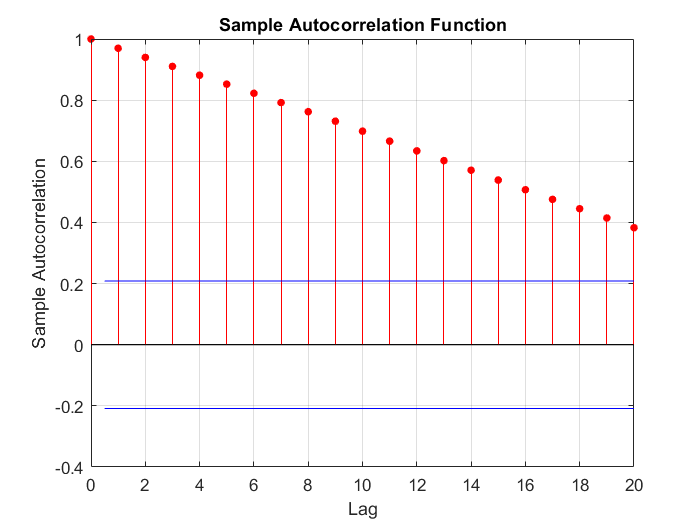


figure
autocorr(Y5)

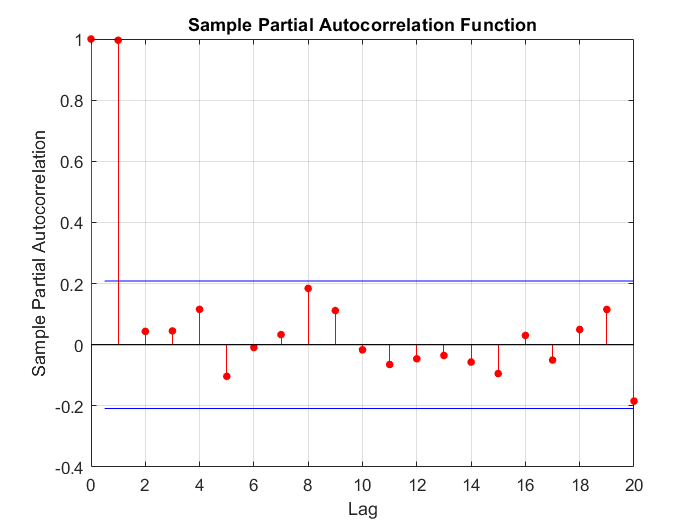

figure
parcorr(Y5)


acf = autocorr(Y5,'NumLags',15)

acf =     1.0000
    0.9697
    0.9398
    0.9104
    0.8815
    0.8523
    0.8225
    0.7920
    0.7622
    0.7312


pacf = parcorr(Y5,'NumLags',15)

pacf =     1.0000
    0.9960
    0.0437
    0.0451
    0.1156
   -0.1033
   -0.0094
    0.0331
    0.1842
    0.1116


[length(acf) length(pacf)]

ans =     16    16


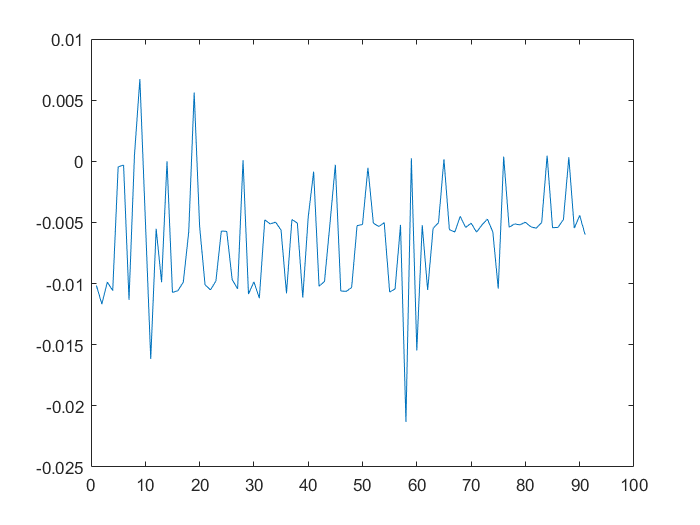


% https://kr.mathworks.com/help/econ/box-jenkins-differencing-vs-arima-estimation.html
%YDiff5 = Y5(2:end) - Y5(1:end-1);
YDiff5 = diff(Y5);

figure 
plot(YDiff5)

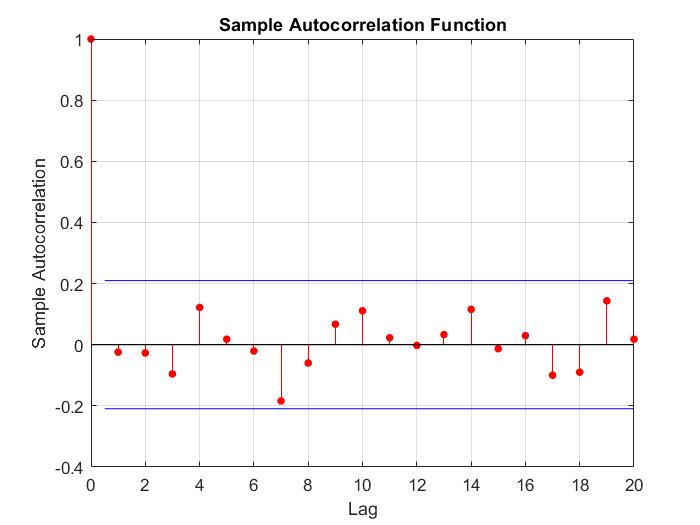

figure
autocorr(YDiff5)

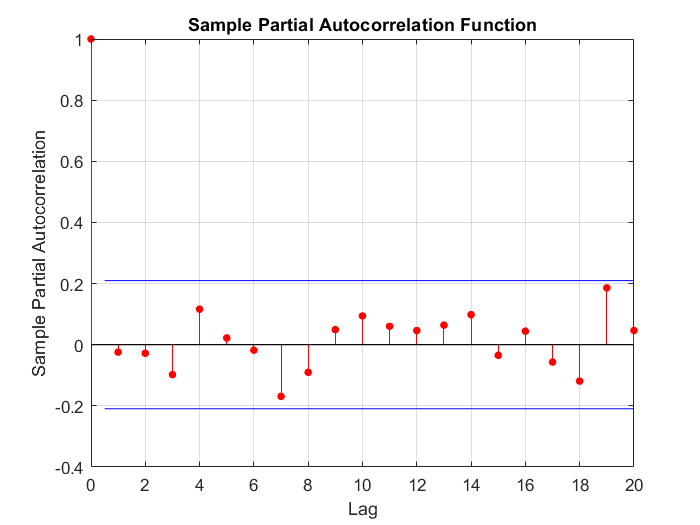

figure
parcorr(YDiff5)

learning_end_index = idx_0506-1;
est_length = length(Y5) - learning_end_index;
end_index = length(Y5);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,Y5(idxest),...
    'Y0',Y5(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061576     0.00054216       -11.357      6.8085e-30
    Variance    1.5405e-05     1.7503e-06        8.8011      1.3542e-18



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00615759
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54046e-05

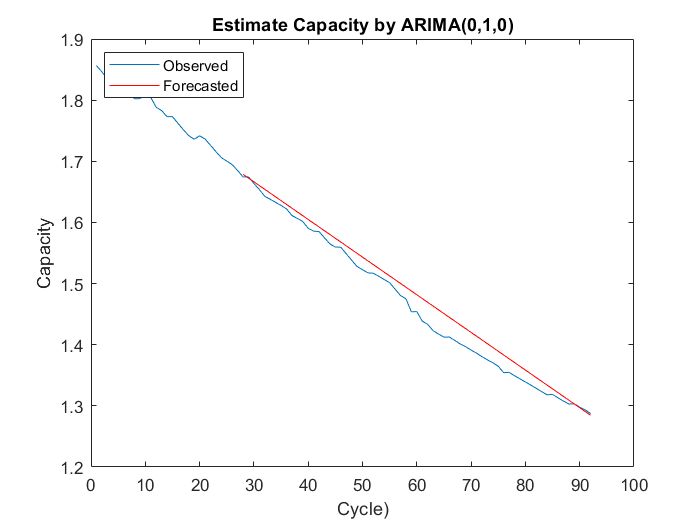


yf0 = Y5(idxpre(end - 1:end));
%yf0 = Y5(idxpre(1:end));

yf = forecast(EstMdl,est_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(Y5);
hold on
h2 = plot([(learning_end_index+1):end_index],yf,'r');
%h2 = plot([Y5(1:learning_end_index);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate Capacity by ARIMA(0,1,0)")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% p,q => max 3 
% to avoid this message
% The error message “the non-seasonal autoregressive polynomial is unstable” 
% https://kr.mathworks.com/matlabcentral/answers/261576-the-non-seasonal-moving-average-polynomial-is-non-invertible
[minP,minQ,minBIC,BIC]=checkArima_v2(cap_05,1,3,3)

minP = 2

minQ = 2

minBIC = -724.7554

BIC =  -722.2795 -717.7998 -713.4389
 -718.3285 -724.7554 -720.1612
 -714.7093 -720.1818 -715.3351


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_05,2,3,3)

minP = 1

minQ = 1

minBIC = -718.3263

BIC =  -718.3263 -717.3229 -712.7333
 -713.7223 -713.6218 -708.1408
 -705.0902 -709.0197 -710.0904


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_06,1,3,3)

minP = 3

minQ = 2

minBIC = -857.3249

BIC =  -838.3193 -852.0439 -853.5284
 -842.8156 -851.8478 -849.1545
 -844.1552 -857.3249 -851.1524


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_06,2,3,3)

minP = 2

minQ = 2

minBIC = -860.0792

BIC =  -846.7771 -856.2269 -853.7029
 -848.6873 -860.0792 -853.5821
 -844.3363 -855.8252 -852.7296


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0506,1,3,3)

minP = 3

minQ = 2

minBIC = -814.5362

BIC =  -813.8205 -809.2999 -805.3553
 -809.6146 -814.2481 -811.2420
 -805.0634 -814.5362 -806.4237


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0506,2,3,3)

minP = 1

minQ = 1

minBIC = -809.9669

BIC =  -809.9669 -807.7756 -803.8899
 -806.6289 -804.5964 -796.9161
 -802.5654 -800.0014 -802.0435


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0605,1,3,3)

minP = 2

minQ = 1

minBIC = -754.8238

BIC =  -752.7218 -753.7283 -738.5870
 -754.8238 -750.2187 -747.7608
 -750.6816 -749.2636 -745.5525


[minP,minQ,minBIC,BIC]=checkArima_v2(cap_0605,2,3,3)

minP = 1

minQ = 1

minBIC = -759.4291

BIC =  -759.4291 -754.8240 -752.3660
 -755.2868 -753.7546 -749.8555
 -752.9167 -745.7930 -749.9848



% battery 5 - arima 113
learning_end_index = idx_0506-1;
est_length = length(Y5) - learning_end_index;
end_index = length(Y5);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl5_base = arima(0,1,0);
Mdl5_opt = arima(1,1,3);  % 0 1 0
%Mdl5_223 = arima(2,2,3); 

EstMdl5_base = estimate(Mdl5_base,Y5(idxest),'Y0',Y5(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061576     0.00054216       -11.357      6.8085e-30
    Variance    1.5405e-05     1.7503e-06        8.8011      1.3542e-18



EstMdl5_opt = estimate(Mdl5_opt,Y5(idxest),'Y0',Y5(idxpre));

 
    ARIMA(1,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0060472       0.005044         -1.1989       0.23057
    AR{1}            2e-12        0.81582      2.4515e-12             1
    MA{1}         -0.11893        0.82146        -0.14478       0.88488
    MA{2}          0.18447        0.14357          1.2849       0.19884
    MA{3}        -0.063126        0.22203        -0.28432       0.77617
    Variance    1.4423e-05     1.8584e-06          7.7612    8.4145e-15



%EstMdl5_223 = estimate(Mdl5_223,Y5(idxest),'Y0',Y5(idxpre)); % error - Nonseasonal MA polyxx in noninverible

%yf5_pre = Y5(idxpre(end - 1:end));
yf5_pre = Y5(idxpre(1:end));

yf5_base = forecast(EstMdl5_base,est_length,yf5_pre);
yf5_opt = forecast(EstMdl5_opt,est_length,yf5_pre);
%yf223 = forecast(EstMdl5_223,est_length,yf5_pre);

%Plot the first xxx observations and the forecasts.
EstMdl5_base

EstMdl5_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00615759
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.54046e-05

EstMdl5_opt

EstMdl5_opt =   arima with properties:

     Description: "ARIMA(1,1,3) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 3
        Constant: -0.00604721
              AR: {2e-12} at lag [1]
             SAR: {}
              MA: {-0.118932 0.184473 -0.0631257} at lags [1 2 3]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.44231e-05

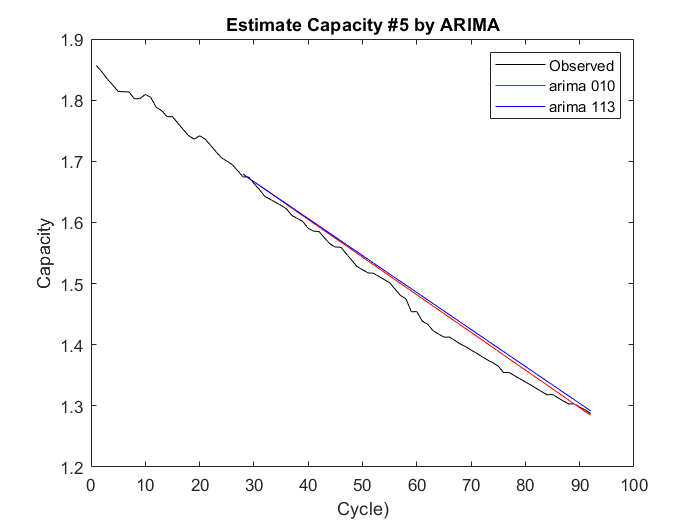




figure
plot(Y5,'k');
hold on
plot([(learning_end_index+1):end_index],yf5_base,'r');
plot([(learning_end_index+1):end_index],yf5_opt,'b');
%plot([(learning_end_index+1):end_index],yf223,'g');
legend("Observed","arima 010", 'arima 113')%,"arima_223")
title("Estimate Capacity #5 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 6 - arima 312
earning_end_index = idx_0605-1;
idx_0506-1;
27;
est_length = length(Y6) - learning_end_index;
end_index = length(Y6);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl6_base = arima(0,1,0);
Mdl6_opt = arima(3,1,2);  % 0 1 0

EstMdl6_base = estimate(Mdl6_base,Y6(idxest),'Y0',Y6(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0071336     0.00062538       -11.407      3.8681e-30
    Variance       2.2e-05     3.2077e-06        6.8586      6.9523e-12



EstMdl6_opt = estimate(Mdl6_opt,Y6(idxest),'Y0',Y6(idxpre));

 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -0.00016301     8.3607e-05        -1.9498       0.051204
    AR{1}            1.5071        0.16475         9.1478     5.8117e-20
    AR{2}          -0.46419        0.27863         -1.666        0.09572
    AR{3}         -0.067916        0.14132       -0.48059        0.63081
    MA{1}           -1.9318       0.049833        -38.765              0
    MA{2}                 1       0.049148         20.347     4.9532e-92
    Variance     1.4632e-05     2.2028e-06         6.6425     3.0851e-11




%yf6_pre = Y6(idxpre(end - 1:end));
yf6_pre = Y6(idxpre(1:end));

yf6_base = forecast(EstMdl6_base,est_length,yf6_pre);
yf6_opt = forecast(EstMdl6_opt,est_length,yf6_pre);


%Plot the first xxx observations and the forecasts.
EstMdl6_base

EstMdl6_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00713359
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.20003e-05

EstMdl6_opt

EstMdl6_opt =   arima with properties:

     Description: "ARIMA(3,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 2
        Constant: -0.000163015
              AR: {1.50711 -0.464195 -0.0679159} at lags [1 2 3]
             SAR: {}
              MA: {-1.93179 1} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.46318e-05

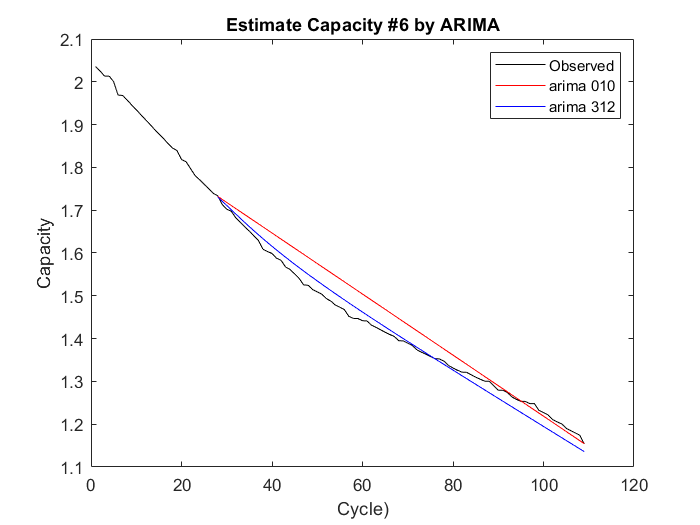




figure
plot(Y6,'k');
hold on
plot([(learning_end_index+1):end_index],yf6_base,'r');
plot([(learning_end_index+1):end_index],yf6_opt,'b');
legend("Observed","arima 010", 'arima 312')
title("Estimate Capacity #6 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 65 - arima 313

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

% to get EstMdl65_base to use 56
learning_end_index = idx_0605-1;
est_length = length(Y65) - learning_end_index;
end_index = length(Y65);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl65_base = arima(0,1,0);



EstMdl65_base = estimate(Mdl65_base,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061764     0.00054918       -11.247      2.4088e-29
    Variance    1.5877e-05     1.8791e-06        8.4495      2.9262e-17




learning_end_index = idx_0506-1;
est_length = length(Y56) - learning_end_index;
end_index = length(Y56);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl56_base = arima(0,1,0);
Mdl56_opt = arima(3,1,3);  


EstMdl56_base = estimate(Mdl56_base,Y56(idxest),'Y0',Y56(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     -0.006783     0.00059187        -11.46      2.0911e-30
    Variance    1.9558e-05     2.6925e-06         7.264      3.7583e-13



EstMdl56_opt = estimate(Mdl56_opt,Y56(idxest),'Y0',Y56(idxpre));

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0068603       0.012623        -0.54349       0.58679
    AR{1}                0         1.2489               0             1
    AR{2}                0        0.86396               0             1
    AR{3}            2e-12        0.93389      2.1416e-12             1
    MA{1}        -0.057919         1.2832       -0.045135         0.964
    MA{2}         0.078206        0.89927        0.086966        0.9307
    MA{3}          0.12233        0.98342          0.1244         0.901
    Variance    1.8875e-05 


%yf56_pre = Y56(idxpre(end - 1:end)); % error - Y0 at least 4
yf56_pre = Y56(idxpre(1:end)); 
yf56_base = forecast(EstMdl56_base,est_length,yf56_pre);
yf56_opt = forecast(EstMdl56_opt,est_length,yf56_pre);
yf56_by_5 = forecast(EstMdl5_base,est_length,yf56_pre);
yf56_by_6 = forecast(EstMdl6_base,est_length,yf56_pre);
yf56_by_65 = forecast(EstMdl65_base,est_length,yf56_pre);
EstMdl56_base

EstMdl56_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00678296
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.9558e-05

EstMdl56_opt

EstMdl56_opt =   arima with properties:

     Description: "ARIMA(3,1,3) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 3
        Constant: -0.00686033
              AR: {2e-12} at lag [3]
             SAR: {}
              MA: {-0.0579186 0.0782059 0.122334} at lags [1 2 3]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.88752e-05

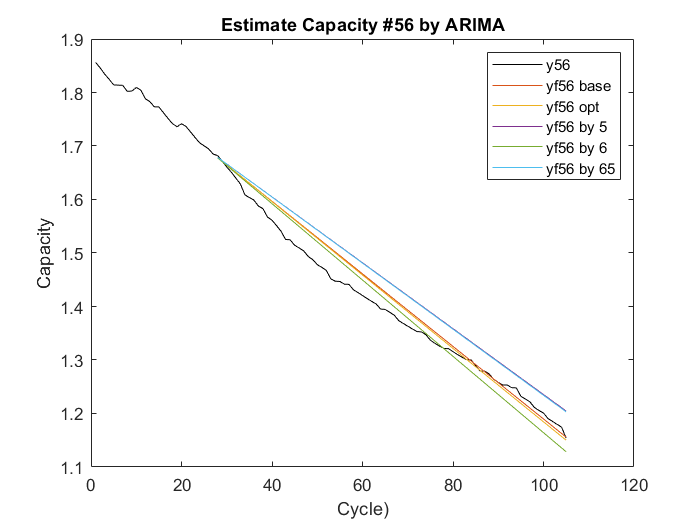


figure
plot(Y56,'k');
hold on
plot([(learning_end_index+1):end_index],yf56_base);
plot([(learning_end_index+1):end_index],yf56_opt);
plot([(learning_end_index+1):end_index],yf56_by_5);
plot([(learning_end_index+1):end_index],yf56_by_6);
plot([(learning_end_index+1):end_index],yf56_by_65);
legend('y56','yf56 base','yf56 opt','yf56 by 5','yf56 by 6','yf56 by 65')
title("Estimate Capacity #56 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 65   arima 111
%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

learning_end_index = 30;
est_length = length(Y65) - learning_end_index;
end_index = length(Y65);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl65_base = arima(0,1,0);
Mdl65_opt = arima(1,1,1);  


EstMdl65_base = estimate(Mdl65_base,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0061764     0.00054918       -11.247      2.4088e-29
    Variance    1.5877e-05     1.8791e-06        8.4495      2.9262e-17



EstMdl65_opt = estimate(Mdl65_opt,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0098116      0.0021281       -4.6106      4.0154e-06
    AR{1}         -0.57686        0.32912       -1.7527        0.079648
    MA{1}          0.42931        0.36856        1.1648         0.24409
    Variance    1.4829e-05     1.7321e-06        8.5617      1.1122e-17




%yf56_pre = Y65(idxpre(end - 1:end)); % error - Y0 at least 4
yf65_pre = Y65(idxpre(1:end)); 
yf65_base = forecast(EstMdl65_base,est_length,yf65_pre);
yf65_opt = forecast(EstMdl65_opt,est_length,yf65_pre);
yf65_by_5 = forecast(EstMdl5_base,est_length,yf65_pre);
yf65_by_6 = forecast(EstMdl6_base,est_length,yf65_pre);
yf65_by_56 = forecast(EstMdl56_base,est_length,yf65_pre);

EstMdl65_base

EstMdl65_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00617638
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.58771e-05

EstMdl65_opt

EstMdl65_opt =   arima with properties:

     Description: "ARIMA(1,1,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 1
        Constant: -0.00981157
              AR: {-0.576858} at lag [1]
             SAR: {}
              MA: {0.429308} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.48293e-05

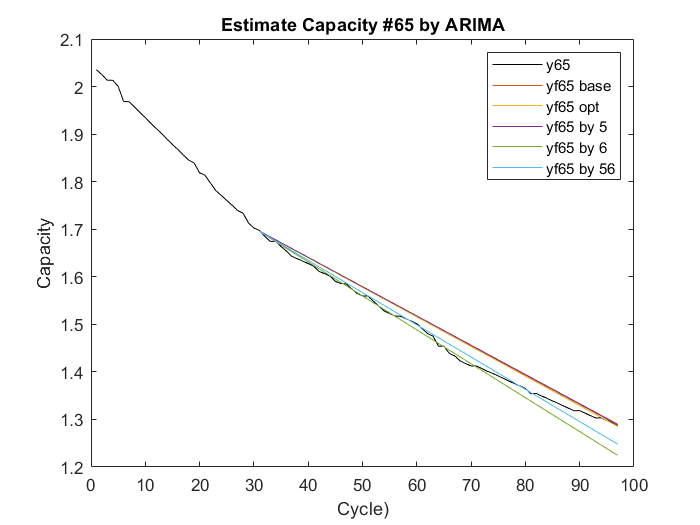


figure
plot(Y65,'k');
hold on
plot([(learning_end_index+1):end_index],yf65_base);
plot([(learning_end_index+1):end_index],yf65_opt);
plot([(learning_end_index+1):end_index],yf65_by_5);
plot([(learning_end_index+1):end_index],yf65_by_6);
plot([(learning_end_index+1):end_index],yf65_by_56);
title("Estimate Capacity #65 by ARIMA")
legend('y65','yf65 base','yf65 opt','yf65 by 5','yf65 by 6','yf65 by 56')
xlabel("Cycle)")
ylabel("Capacity")
hold off

RMSE

%{
RMSE_5_by_5 = sqrt(mean(( Y5' - yf5_opt' ).^2))
RMSE_6_by_6 = sqrt(mean(( Y6' - yf6_opt' ).^2))
RMSE_56_by_05 = sqrt(mean(( Y56' - yf56_by_5 ).^2))
RMSE_56_by_06 = sqrt(mean(( Y56' - yf56_by_6 ).^2))
RMSE_65_by_05 = sqrt(mean(( Y65' - yf65_by_5 ).^2))
RMSE_65_by_06 = sqrt(mean(( Y65' - yf65_by_6 ).^2))
%}


RMSE_56_by_05 = sqrt(mean(( Y56(idx_0506:end) - yf56_by_5 ).^2))

RMSE_56_by_05 = 0.0479

RMSE_56_by_06 = sqrt(mean(( Y56(idx_0506:end) - yf56_by_6 ).^2))

RMSE_56_by_06 = 0.0280

RMSE_65_by_05 = sqrt(mean(( Y65(idx_0605:end) - yf65_by_5 ).^2))

RMSE_65_by_05 = 0.0245

RMSE_65_by_06 = sqrt(mean(( Y65(idx_0605:end) - yf65_by_6 ).^2))

RMSE_65_by_06 = 0.0225